# Phase portraits of linear equations

## negative real roots

A = 1;  B = 8;  C = 4;
s = roots([A B C])

s =   -7.4641e+00
  -5.3590e-01


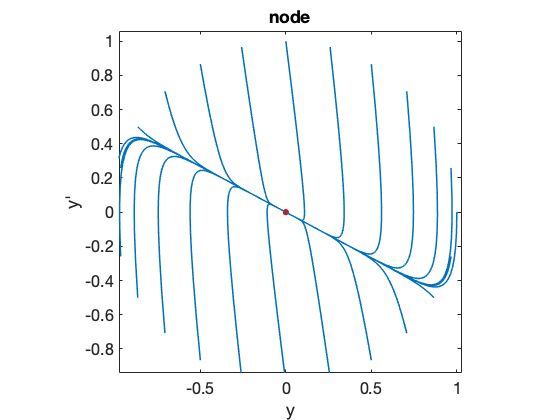


plot(0,0,'r.','markersize',18)
    
% Plot trajectories
hold on
colr = get(gca,'colororder');
t = linspace(0,10,300);
for theta = 2*pi*(0:23)/24
    c = [1 1;s(1) s(2)] \ [ cos(theta); sin(theta) ];
    y = c(1)*exp(s(1)*t) + c(2)*exp(s(2)*t);
    dydt = s(1)*c(1)*exp(s(1)*t) + s(2)*c(2)*exp(s(2)*t);
    plot(y,dydt,'linew',1.5,'color',colr(1,:))
end

axis([-1.1 1.1 -1.1 1.1]), axis square
title(['node'])
xlabel('y')
ylabel('y''')

## real roots different signs

A = 1;  B = 6;  C = -3;
s = sort(roots([A B C]),'descend')

s =    4.6410e-01
  -6.4641e+00


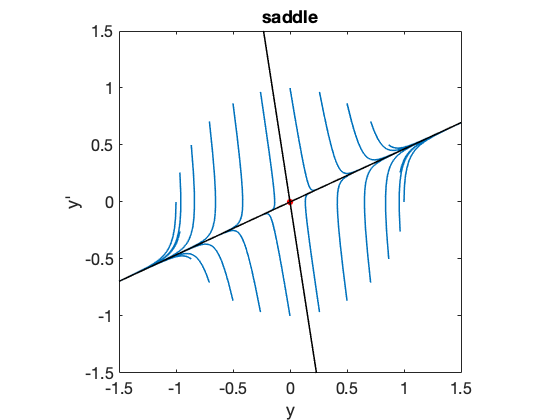


clf, plot(0,0,'r.','markersize',18)
    
% Plot trajectories
hold on
colr = get(gca,'colororder');
t = linspace(0,15,300)';
for theta = 2*pi*(0:23)/24
    c = [1 1;s(1) s(2)] \ [ cos(theta); sin(theta) ];
    y = c(1)*exp(s(1)*t) + c(2)*exp(s(2)*t);
    dydt = s(1)*c(1)*exp(s(1)*t) + s(2)*c(2)*exp(s(2)*t);
    plot(y,dydt,'linew',1.5,'color',colr(1,:))
end
y = 2*exp(s(2)*t); dydt = 2*s(2)*exp(s(2)*t);
plot([y -y],[dydt -dydt],'k','linew',1.5)
y = 2*exp(-s(1)*t); dydt = 2*s(1)*exp(-s(1)*t);
plot([y -y],[dydt -dydt],'k','linew',1.5)

axis([-1.5 1.5 -1.5 1.5]), axis square
title('saddle')
xlabel('y')
ylabel('y''')

## imaginary roots

A = 1;  B = 0;  C = 2;
s = roots([A B C])
disp(s)

   0.0000e+00 + 1.4142e+00i
   0.0000e+00 - 1.4142e+00i



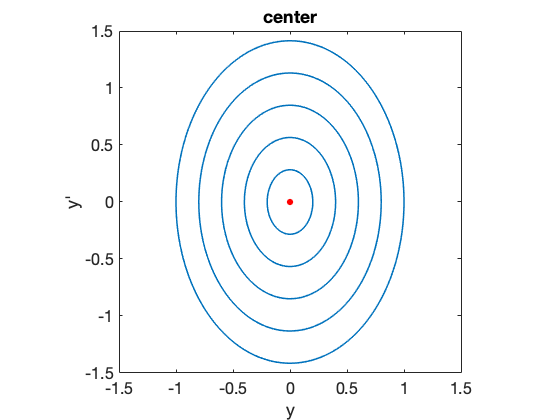


clf, plot(0,0,'r.','markersize',18)
    
% Plot trajectories
hold on
colr = get(gca,'colororder');
t = linspace(0,15,1000)';
for R = .2:.2:1
    y = R*real(exp(s(1)*t));
    dydt = R*real(s(1)*exp(s(1)*t));
    plot(y,dydt,'linew',1.5,'color',colr(1,:)), hold on
end
axis([-1.5 1.5 -1.5 1.5]), axis square
title('center')
xlabel('y')
ylabel('y''')

## complex roots

A = 1;  B = .6;  C = 3;
s = roots([A B C])
disp(s)

  -3.0000e-01 + 1.7059e+00i
  -3.0000e-01 - 1.7059e+00i



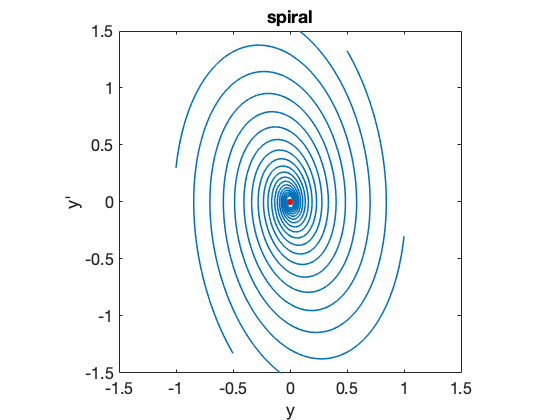


clf, plot(0,0,'r.','markersize',18)
    
% Plot trajectories
hold on
colr = get(gca,'colororder');
t = linspace(0,12,1000)';
for phi = 2*pi*(0:5)/6
    y = real(exp(s(1)*t-1i*phi));
    dydt = real(s(1)*exp(s(1)*t-1i*phi));
    plot(y,dydt,'linew',1.5,'color',colr(1,:)), hold on
end
axis([-1.5 1.5 -1.5 1.5]), axis square
title('spiral')
xlabel('y')
ylabel('y''')